# Homework 2: Comparison of Triplet and Stacking Weighing Methods in Model Estimation 

## 4 April 2026 by Ji,Haozheng

## Using the Triplet Weighing Method

## (a) Randomly assigns masses $m_{true}$ to the objects in the range of 0-1 kg

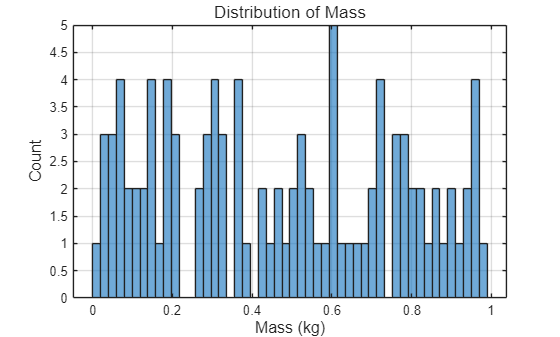

clc; clear; close all; 
rng(42);
n_m=100;
m_true = rand(n_m,1);
figure;
histogram(m_true, 50);
xlabel('Mass (kg)', 'FontSize', 12);
ylabel('Count', 'FontSize', 12);
title('Distribution of Mass', 'FontSize', 13);
grid on;
box on;
exportgraphics(gcf, 'mass_distribution.png', 'Resolution', 300);

### (b) Build the appropriate kernel $G$

step 1. weight the first

step 2. weight the first and second

step n. weight the rest in triplets

G_tri=eye(n_m,n_m);
G_tri(2,1)=1;
for ii = 3:1:n_m
    G_tri(ii,ii-2:ii-1)=1;
end

### (c) Creates synthetic observed data $d_{obs}=Gm+n$ , where $n$ is a vector of Gaussian random number with zero mean and $\sigma_d=0.01kg$

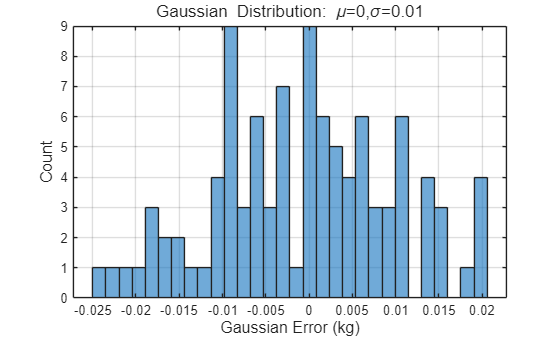

mu=0;
sigma=0.01;
n=mu+sigma*randn(n_m,1);
d_tri=G_tri*m_true+n;
figure;
histogram(n,30);
xlabel('Gaussian Error (kg)', 'FontSize', 12);
ylabel('Count', 'FontSize', 12);
title('Gaussian Distribution: \mu=0,\sigma=0.01','FontSize',13)
grid on;
box on;
exportgraphics(gcf, 'error_distribution.png', 'Resolution', 300);

### (d) Solves the inverse problem by simple least square

$Gm=d_{obs}$, $m_{inv}=(G^\top G)^{-1}G^\top d_{obs}$

G_gtri=(G_tri'*G_tri)\G_tri';
m_tri=G_gtri*d_tri;

### （e) Estimates the variance of each of the estimated model parameters $m_{est}$

$m_{est}=G_gd$, $\text{cov}[m]=G_g\text{cov}[d]G_g^\top$, and we have $\text{cov}[d]=0.01^2$ .

The diagonal element are the corresponding variance of model parameters.

covar_tri=sigma^2*(G_gtri*G_gtri');
var_tri=diag(covar_tri);
sigma_tri=sqrt(var_tri);

### (f) Counts up the number of estimated model parameters that are within $\pm   2\sigma_m$

res_tri=m_tri-m_true;
counts_tri=sum(abs(res_tri)-2*sigma_tri<=0);
fprintf('Triplet Weighing Method: Number of parameters within ±2σ_m of true value: %d / %d\n', ...
    counts_tri, n_m);

Triplet Weighing Method: Number of parameters within ±2σ_m of true value: 98 / 100


### (g) Make a plot of $\sigma_m$ as a function of the index of the model parameters

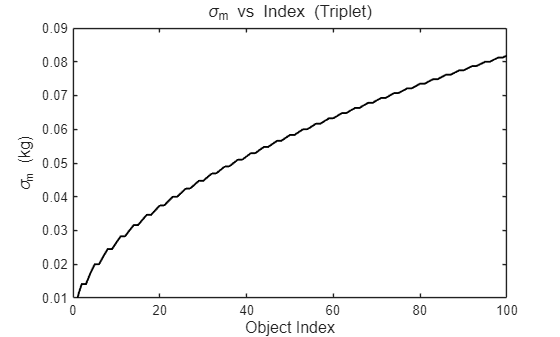

figure;
idx=1:n_m;
plot(idx,sigma_tri,'k',LineWidth=1.4);
xlabel('Object Index','FontSize', 12);
ylabel('\sigma_m (kg)','FontSize', 12)
ax.YAxis.Exponent = -3;
title('\sigma_m vs Index (Triplet)','FontSize', 13)
exportgraphics(gcf, 'Deviation_index_Triplet.png', 'Resolution', 300);

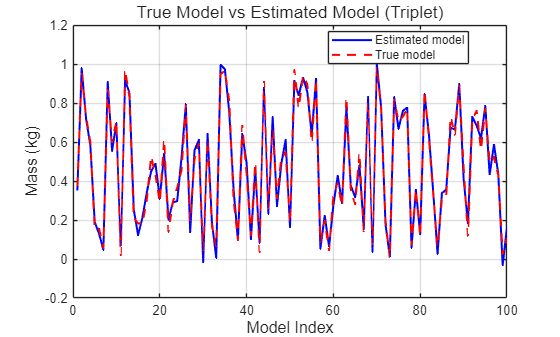

figure;
hold on;
plot(idx, m_tri, 'b-', 'LineWidth', 1.5);
plot(idx, m_true, 'r--', 'LineWidth', 1.5);
xlabel('Model Index','FontSize', 12);
ylabel('Mass (kg)','FontSize', 12);
title('True Model vs Estimated Model (Triplet)','FontSize', 13);
legend('Estimated model','True model','Location','best');
grid on;
box on;
exportgraphics(gcf, 'model_comparison_Triplet.png', 'Resolution', 300);

## Using the Stacking Weighing Method

step 1. weight the first

step 2. weight the first and second

step n. step n. weigh all objects up to n

G_stack=tril(ones(n_m));
d_stack=G_stack*m_true+n;
G_gstack=(G_stack'*G_stack)\G_stack';
m_stack=G_gstack*d_stack;
covar_stack=sigma^2*(G_gstack*G_gstack');
var_stack=diag(covar_stack);
sigma_stack=sqrt(var_stack);
res_stack=m_stack-m_true;
counts_stack=sum(abs(res_stack)-2*sigma_stack<=0);
fprintf('Stacking Weighing Method: Number of parameters within ±2σ_m of true value: %d / %d\n', ...
    counts_stack, n_m);

Stacking Weighing Method: Number of parameters within ±2σ_m of true value: 96 / 100


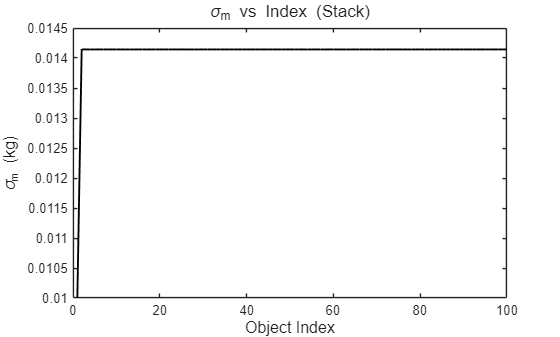

figure;
idx=1:n_m;
plot(idx,sigma_stack,'k',LineWidth=1.4);
xlabel('Object Index','FontSize', 12);
ylabel('\sigma_m (kg)','FontSize', 12)
title('\sigma_m vs Index (Stack)','FontSize', 13)
exportgraphics(gcf, 'Deviation_index_Stacking.png', 'Resolution', 300);

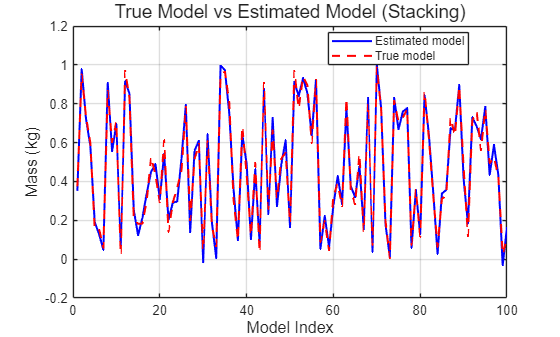

figure;
hold on;
plot(idx, m_tri, 'b-', 'LineWidth', 1.5);
plot(idx, m_true, 'r--', 'LineWidth', 1.5);
xlabel('Model Index','FontSize', 12);
ylabel('Mass (kg)','FontSize', 12);
title('True Model vs Estimated Model (Stacking)','FontSize', 14);
legend('Estimated model','True model','Location','best');
grid on;
box on;
exportgraphics(gcf, 'model_comparison_Stacking.png', 'Resolution', 300);

## Comparison of Triplet and Stacking Weighing Methods

fprintf('Average σ_m - Triplet: %.6f kg\nAverage σ_m - Stacking: %.6f kg\nRMSE - Triplet: %.6f kg\nRMSE - Stacking: %.6f kg\n', mean(sqrt(var_tri)),mean(sqrt(var_stack)),sqrt(mean(res_tri.^2)),sqrt(mean(res_stack.^2)));

Average σ_m - Triplet: 0.055201 kg
Average σ_m - Stacking: 0.014101 kg
RMSE - Triplet: 0.040437 kg
RMSE - Stacking: 0.014222 kg


### Compare the covariance and model resolution

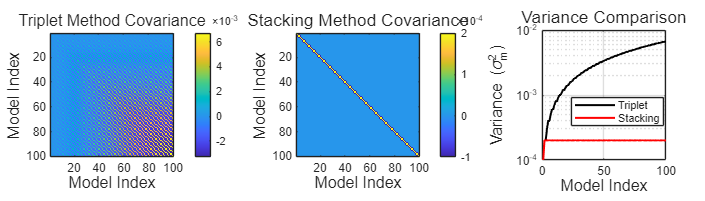

figure('Position',[100,100,1400,400]);
t = tiledlayout(1,3,'TileSpacing','Compact','Padding','Compact');
nexttile
imagesc(covar_tri);
colorbar;
axis image;
xlabel('Model Index','FontSize',12);
ylabel('Model Index','FontSize',12);
title('Triplet Method Covariance','FontSize',12);
nexttile
imagesc(covar_stack);
colorbar;
axis image;
xlabel('Model Index','FontSize',12);
ylabel('Model Index','FontSize',12);
title('Stacking Method Covariance','FontSize',13);
nexttile
hold on
plot(1:n_m, var_tri, 'k-', 'LineWidth', 1.5);
plot(1:n_m, var_stack, 'r-', 'LineWidth', 1.5);
xlabel('Model Index','FontSize',12);
ylabel('Variance (\sigma_m^2)','FontSize',12);
title('Variance Comparison','FontSize',13);
legend('Triplet','Stacking','Location','best');
set(gca,'YScale','log');
grid on;
box on;
exportgraphics(gcf, 'covariance_comparison.png', 'Resolution', 300);

# Analysis

When using the Stacking Method, each measurement includes more objects, but the measurement deviation is fixed. The more objects included in a measurement, the smaller the portion of error shared by each object, approximately $\frac{\varepsilon}{N}$ which decreases toward zero as $N\rightarrow \infty$. In contrast, in the Triplet Method, each measurement always involves three objects, and the error is shared equally among them (approximately $\frac{\varepsilon}{3}$), which does not decrease as the model grows. As a result, the Triplet Method accumulates more uncertainty for later objects, while the Stacking Method produces more stable and smaller variance for all estimated masses.

## Resolution

- Triplet Method: Covariance matrices (also can be written as $G^\top G$) are **scattered** showing many model parameters contribute to one estimated value, resulting in **poor resolution**.  

- Stacking Method: Covariance matrices are **approximately** **diagonal** indicating each estimated parameter is mainly determined by its corresponding true value, giving **high resolution**.

## Root Mean Square Error (RMSE)

- Trend: For the Triplet Method, RMSE **increases** with the number of model parameters ($N$), indicating accuracy deteriorates for larger models.  

- Size: Triplet RMSE is generally **larger** than Stacking RMSE, while Stacking RMSE remains **small and stable** across all model sizes.

## Standard Deviation ($\sigma_m$)

- Trend: For the Triplet Method, $\sigma_m$ **increases** with $N$, reflecting that uncertainty accumulates for later parameters.  For the Stacking Method, $\sigma_m$ remains **stable**, showing consistent uncertainty across all parameters.  

- Size: Triplet $\sigma_m$ is generally **larger** than Stacking $\sigma_m$, which is **smaller** and well-controlled.